## Load functions

% this file should be in the same directory as the /functions dir
% restoredefaultpath;
addpath(['~/Documents/Courses/'...
    'ELEC-E5620 Audio Signal Processing/'...
    'Demo_FVN/matlab/functions']);

# All-pass Cascade

"The delay line lengths of the SAP filters are 225, 341, 441, and 556 samples, and their filter coefficient is *a *= 0.7. " p.7

confirm all-pass decay is (1-g)g^n

a_AP = 0.907; % all-pass coefficient
% d_AP = [ 225 ]; % all-pass delays
d_AP = [ 225, 341, 441, 556 ]; % all-pass delays

% sig = [1; zeros(49, 1)];
sig = [1; zeros(49, 1); 1];

% subplot(2,1,1)
% plot(sig)

% NOTE: this will determine the length of the returned signal, based on 
% and energy decay tail cutoff point. Quite crude, as underlying
% calculation assumes low order filters...
rolloff_threshold = -70;

for del = d_AP
    sig = schrdAllpass(sig, a_AP, del, -35);
end

    "IR length at 1% decay: 3579 samples"

    "IR length at 1% decay: 5425 samples"

    "IR length at 1% decay: 7015 samples"

    "IR length at 1% decay: 8844 samples"



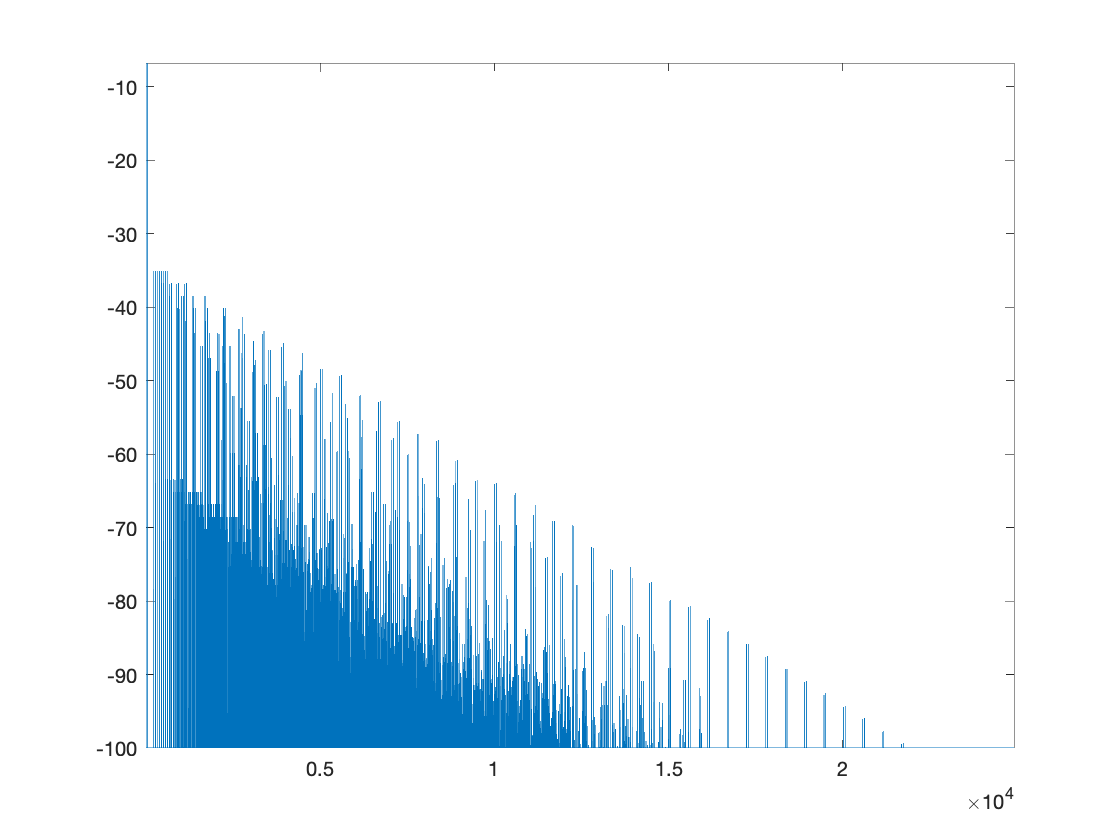


% subplot(2,1,2)
% plot(sig);
% stem(sig);
plot(max(mag2db(sig.^2), -100))
axis tight

# Whiten IR Segments

### Retrieve segments

% n = 100:150:2000;             % time points which to measure [ms]
% M = 100 * ones(length(n), 1);  % durations of segments to measure [ms]
% convert miliseconds to samples
% n = round(n ./1000 .*Fs); 
% M = round(M ./1000 .*Fs);

% use code in 'decay_measurement.mlx' to get segStartIdxs

seg_bounds = [segStartIdxs'; length(X)];
M = seg_bounds(2:end) - seg_bounds(1:end-1);
nSeg = length(M);
segments = {};

for i = 1:nSeg
    st = seg_bounds(i);
    len = M(i);
%     segments{i} = X(st:st+len-1);
    segments{i} = getSamples(X, st, len);
end

clear i M n

#### plot segments

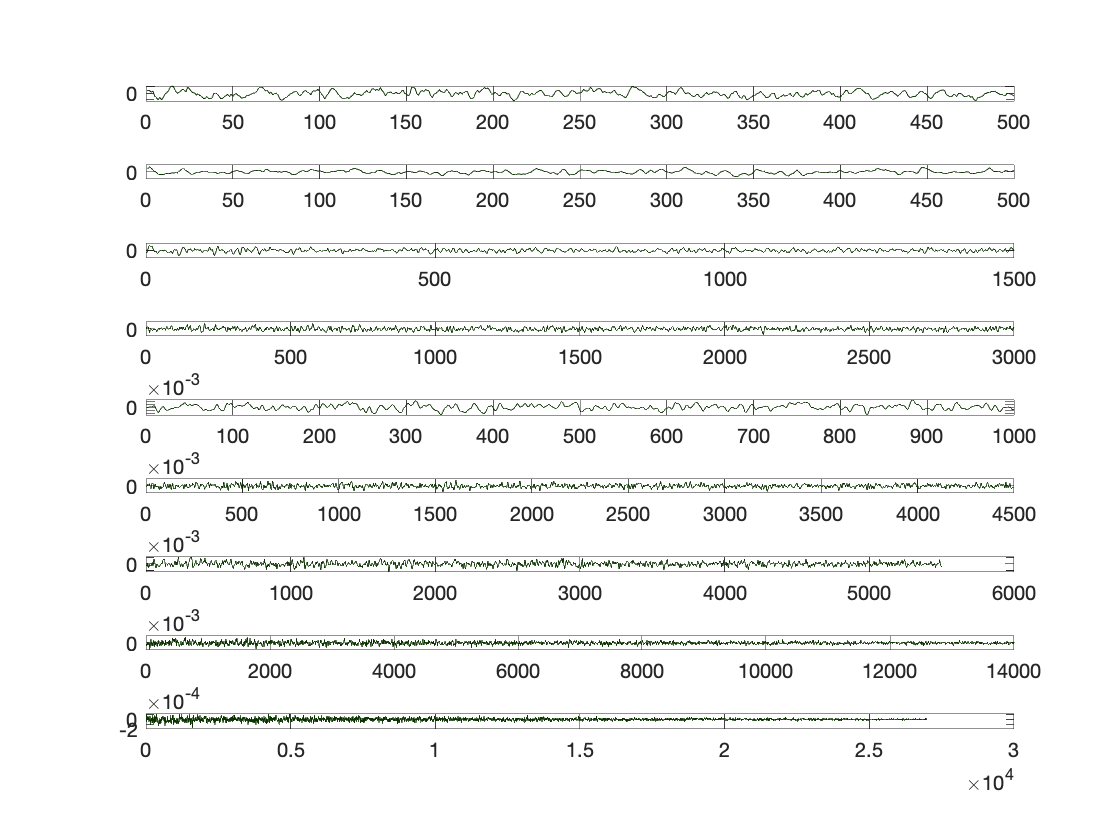

plot_idxs = 1:2:nSeg;
cnt = 1;
for i = plot_idxs
    subplot(length(plot_idxs), 1, cnt)
    plot(segments{i})
    cnt = cnt+1;
end

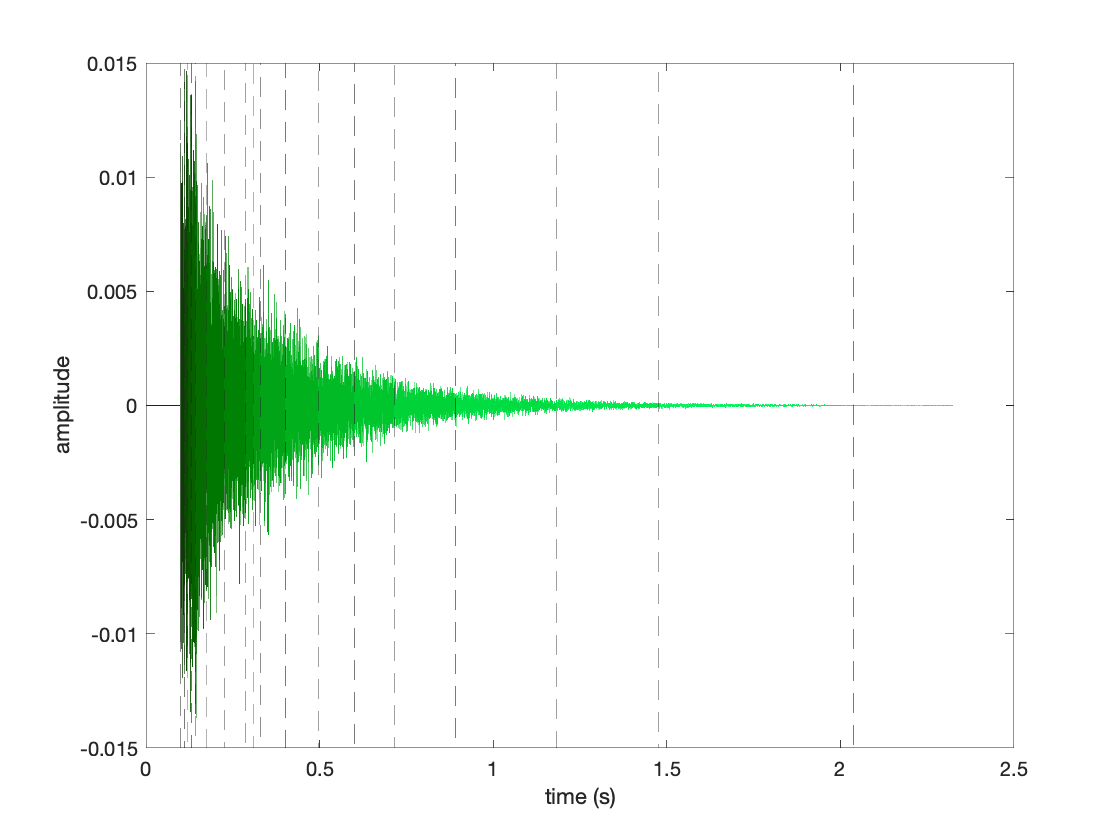


figure();
end_idx = seg_bounds(1)-1;
plot((1:end_idx) ./ Fs, zeros(end_idx, 1)); % inital (unsynthesized) part of response
hold on;
for i = 1:nSeg % seg_bounds is size nSeg+1
    st_idx = seg_bounds(i);
    end_idx = seg_bounds(i+1)-1;
    plot((st_idx:end_idx) ./ Fs, segments{i});
end
for i = 1:nSeg % seg_bounds is size nSeg+1
    st_idx = seg_bounds(i);
    xline(st_idx / Fs, "--");
end
hold off;

% generate colors for plot: hue_start, hue_span, num_plots
rgb = genColors(0.3, 0.1, nSeg+1);
colororder([rgb; rgb]);
ylabel('amplitude');
xlabel('time (s)')

clear plot_idxs cnt

### Generate LPC whitening filters

lpc_order = 10;
whiten = true;
mag_resolution = 2048; % for plotting

% storage
mags_lpc = zeros(mag_resolution, nSeg);
freqs_lpc = zeros(mag_resolution, nSeg);
coeffs_lpc = zeros(lpc_order+1, nSeg);

for i = 1:nSeg
    [mags, ~, freqs, coeffs] = lpcData( ...
        segments{i}, lpc_order, mag_resolution, Fs, whiten);
    mags_lpc(:,i) = mags; % just keep the normalized spectrum for plotting
    freqs_lpc(:,i) = freqs;
    coeffs_lpc(:, i) = coeffs;
end

clear mags mags_norm freqs coeffs

### Plot whitening filter magnitudes

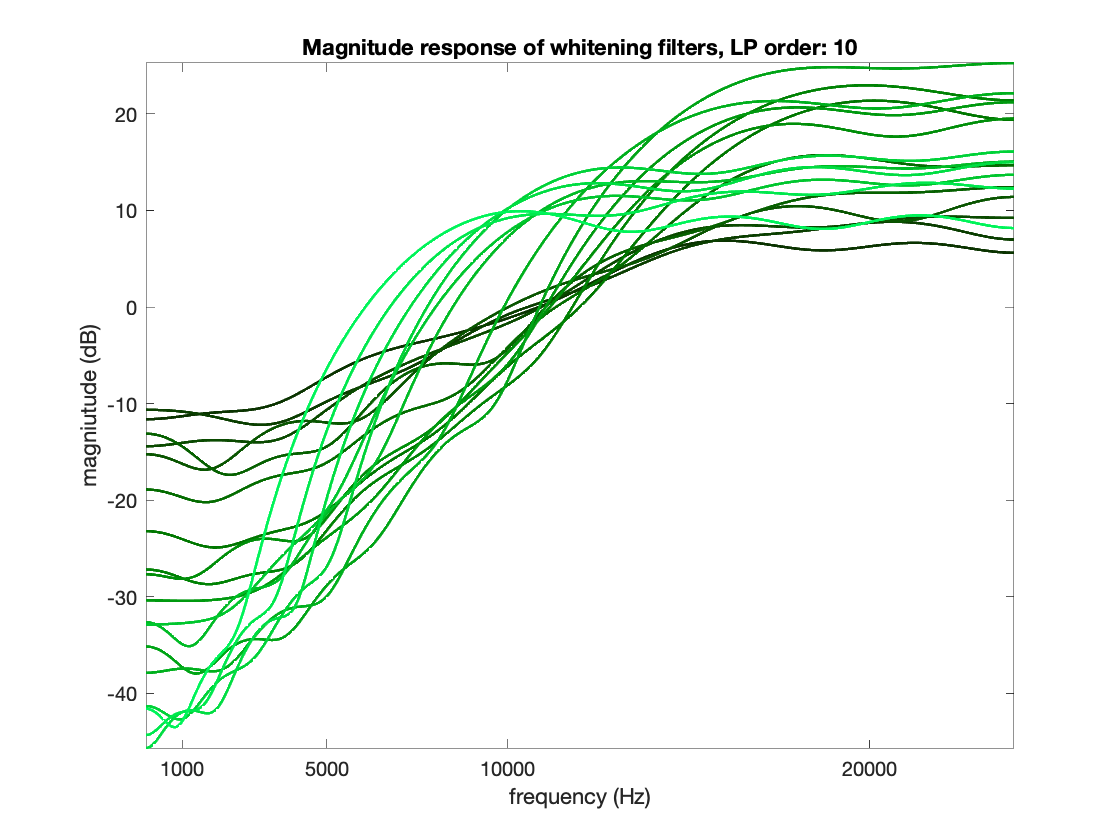

% plt = semilogx(freqs_lpc, mags_lpc);
plt = plot(freqs_lpc, mags_lpc);
% disp(plt(:).LineWidth)
set(plt,'LineWidth',1.5)
axis tight;
colororder(rgb);
xlabel('frequency (Hz)')
ylabel('magniutude (dB)')
xticks(1000 * [1, 5, 10, 20])
xticklabels(1000 * [1, 5, 10, 20])
title(sprintf("Magnitude response of whitening filters, LP order: %d", lpc_order))

# Whiten the segments, measure their power

% "whiten" the original segments
segments_white = {};
for i = 1:nSeg
    segments_white{i} = filter(coeffs_lpc(:, i), [1], segments{i});
end

% recompute spectrum estimate ... is it flat?
% storage
mags_lpc_whitened = zeros(mag_resolution, nSeg);
freqs_lpc_whitened = zeros(mag_resolution, nSeg);
whiten = false;

for i = 1:nSeg
    [mags, ~, freqs, ~] = lpcData( ...
        segments_white{i}, lpc_order, mag_resolution, Fs, whiten);
    mags_lpc_whitened(:,i) = mags; % just keep the normalized spectrum
    freqs_lpc_whitened(:,i) = freqs;
end

### Plot LP magnitudes of whitened segments

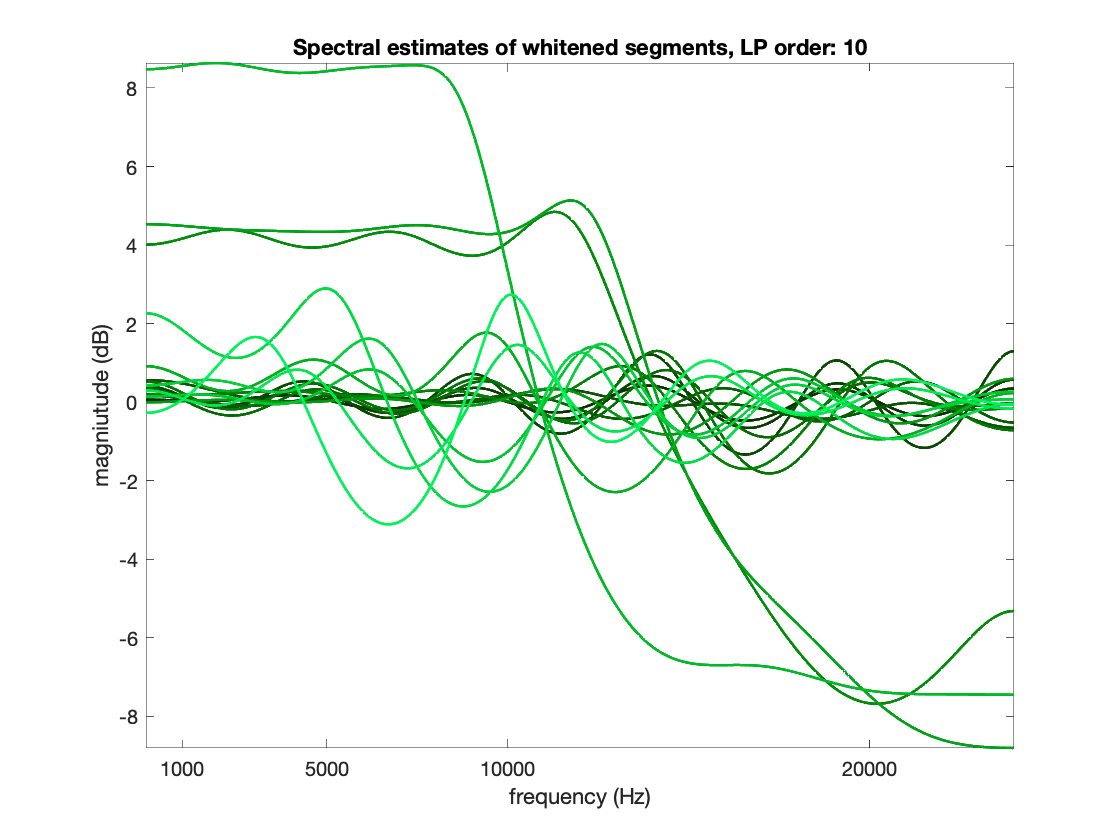

% plt = semilogx(freqs_lpc_whitened, mags_lpc_whitened);
plt = plot(freqs_lpc_whitened, mags_lpc_whitened);
set(plt,'LineWidth',1.5)
axis tight;
colororder(rgb);
xlabel('frequency (Hz)')
ylabel('magniutude (dB)')
xticks(1000 * [1, 5, 10, 20])
xticklabels(1000 * [1, 5, 10, 20])
title(sprintf("Spectral estimates of whitened segments, LP order: %d", lpc_order))


clear freqs_lpc_whitened mags_lpc_whitened ...
    mags mags_norm freqs coeffs

## Analyze signal power of whitened segments

power_whitened = sum(segments_white .^2)

Undefined operator '.^' for input arguments of type 'cell'.

# Velvet Noise Sequences

"*N*d = 100 pulses/s is sufficient in the very beginning of the late reverberation, where segments are very short, whereas *N*d = 40 pulses/s can be enough at the end where the bandwidth gets narrow. Between these extremes, the density is decreased linearly as a function of the segment index *m*." p. 7